# Guía 1 - Ejercicio 3

## Enunciado:

Implemente una red de Hopfield ‘82 que aprenda patrones pseudo-aleatorios y muestre qué sucede con los patrones aprendidos cuando algunas interconexiones son eliminadas al azar. Estime cuánto disminuye la capacidad en función de la eliminación de interconexiones. 

## Solución:

defino los parámetros constantes

close all;
clear all;
N = 1000; % Cantidad de Neuronas.

Con esto me queda definido que tengo $N^2$ conexiones.

capacidadTeorica = uint16(0.105*N); % Cantidad de patrones máximos con los que voy a entrenar a la red.
P_error_teorico = 0.001;

Creo los $p_{max}$ patrones, me fijo si la red tiene el porcentaje de error teórico, si lo tiene 

capacidad = [];
capacidadActual = capacidadTeorica;
for porElim=0:1:100
    ProbErrores=1;
    while ProbErrores>=P_error_teorico && capacidadActual>=0 % Mientras la ProbError sea mayor o igual a la teorica
        % voy bajando la cant de patrones para obtener la capacidad
        patrones = rand([N,capacidadActual]); % Creo la matriz de N x p_max que va a tener p_max patrones.
        patrones = patrones <0.5; % Convierto a 1s y 0s.
        patrones = patrones*2-1; % Convierto a 1s y -1s.
        w = patrones*patrones'; % Creo la matriz de pesos
        w = w/N; %y divido por la cantidad de patrones.
        w = w.*(ones(N)-eye(N)); % Anulo la diagonal
        eliminacion = rand(N)<1-porElim/100; % Creo la matriz de pesos que se van a eliminar
        w=w.*eliminacion; % Elimino esos pesos
        salida = w*patrones; % Calculo la salida con todos los patrones
        salida=negSign(salida); % Convierto a -1s y 1s
        ProbErrores = sum(sum(abs(salida-patrones))); % Sumo los errores
        ProbErrores= ProbErrores/double(capacidadActual*N); % Calculo la probabilidad
        capacidadActual=capacidadActual-1; % Al final bajo la capacidad actual
    end
    capacidadActual = capacidadActual+1;
    capacidad = [capacidad capacidadActual];
end

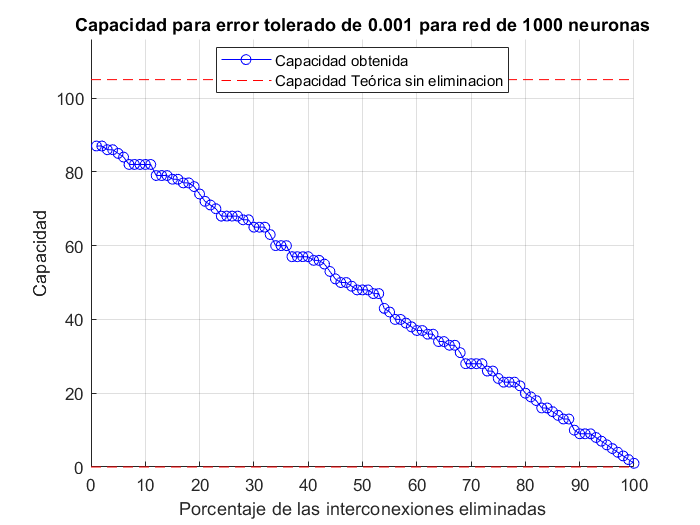

figure(1)
hold on
plot( capacidad, '-ob')
plot([0 100],[capacidadTeorica capacidadTeorica], '--r')
axis([0 100 -1 capacidadTeorica*1.1])
ylabel('Capacidad')
title(sprintf('Capacidad para error tolerado de %.3f para red de %i neuronas', P_error_teorico, N ))
xlabel('Porcentaje de las interconexiones eliminadas')
legend('Capacidad obtenida', 'Capacidad Teórica sin eliminacion', 'Location', 'best')
grid on

En esta parte verifico cómo varía la probabilidad de error para un número de patrones fijo cuando elimino conexiones.

patrones = rand([N,capacidadTeorica]); % Creo la matriz de N x capacidadTeorica.
patrones = patrones <0.5; % Convierto a 1s y 0s.
patrones = patrones*2-1; % Convierto a 1s y -1s.
ProbErrores = zeros([101,1]);
for porElim=0:1:100
    w = patrones*patrones'; % Creo la matriz de pesos
    w = w/N; %y divido por la cantidad de patrones.
    w = w.*(ones(N)-eye(N)); % Anulo la diagonal
    eliminacion = rand(N)<1-porElim/100; % Creo la matriz de pesos que se van a eliminar
    w=w.*eliminacion; % Elimino esos pesos
    salida = w*patrones; % Calculo la salida con todos los patrones
    salida=negSign(salida); % Convierto a -1s y 1s
    ProbErrores(porElim+1) = sum(sum(abs(salida-patrones)))/2; % Sumo los errores
    ProbErrores(porElim+1)= ProbErrores(porElim+1)/(double(N)*double(capacidadTeorica)); % Calculo la probabilidad
end

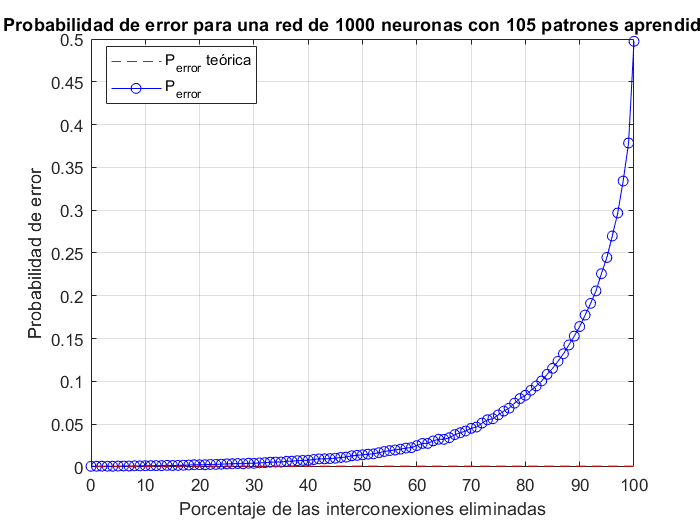

figure(2)
hold on
plot(0:100, ProbErrores, '-ob')
plot([0 101],[P_error_teorico P_error_teorico], '--r')
ylabel('Probabilidad de error')
title(sprintf('Probabilidad de error para una red de %i neuronas con %i patrones aprendidos', N,capacidadTeorica ))
xlabel('Porcentaje de las interconexiones eliminadas')
legend('P_{error} teórica','P_{error}', 'Location', 'best')
grid on
axis([0 100 0 0.5])

Alternativamente puedo graficar como varía $\sigma = \sqrt{p/N}$ que significa cómo varía el ancho que describe al término de Crosstalk.

$P_{error} = P(C_i^\nu > 1)$ donde $C_i^\nu\sim\mathcal{N}(0, \sqrt{p/N})$

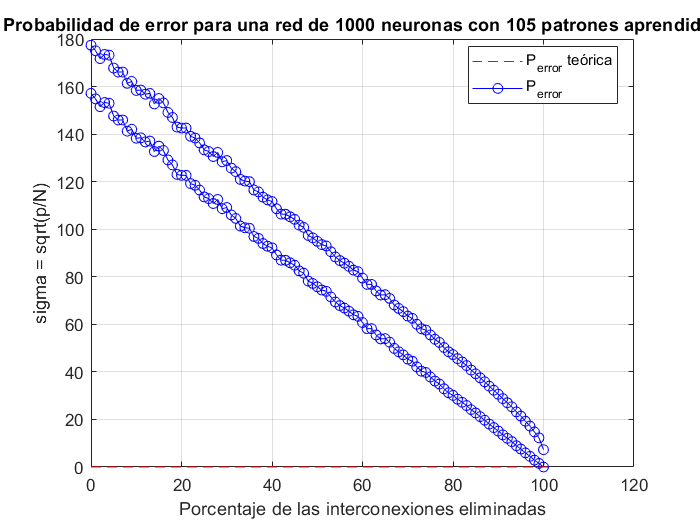

figure(3);
hold on
plot(0:100, erfinv(1-ProbErrores*2), '-ob')
plot([0 101],[P_error_teorico P_error_teorico], '--r')
ylabel('sigma = sqrt(p/N)')
title(sprintf('Probabilidad de error para una red de %i neuronas con %i patrones aprendidos', N,capacidadTeorica ))
xlabel('Porcentaje de las interconexiones eliminadas')
legend('P_{error} teórica','P_{error}', 'Location', 'best')
grid on